# WLAN MAC Basics - Scheduling actions

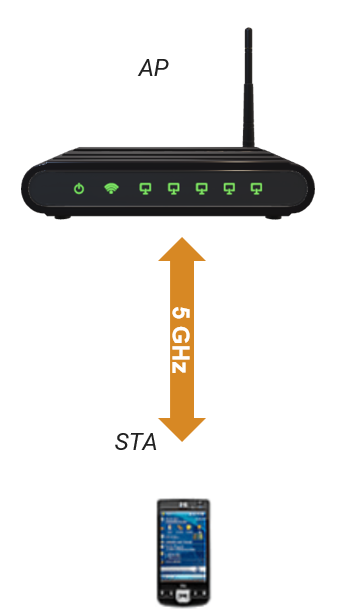

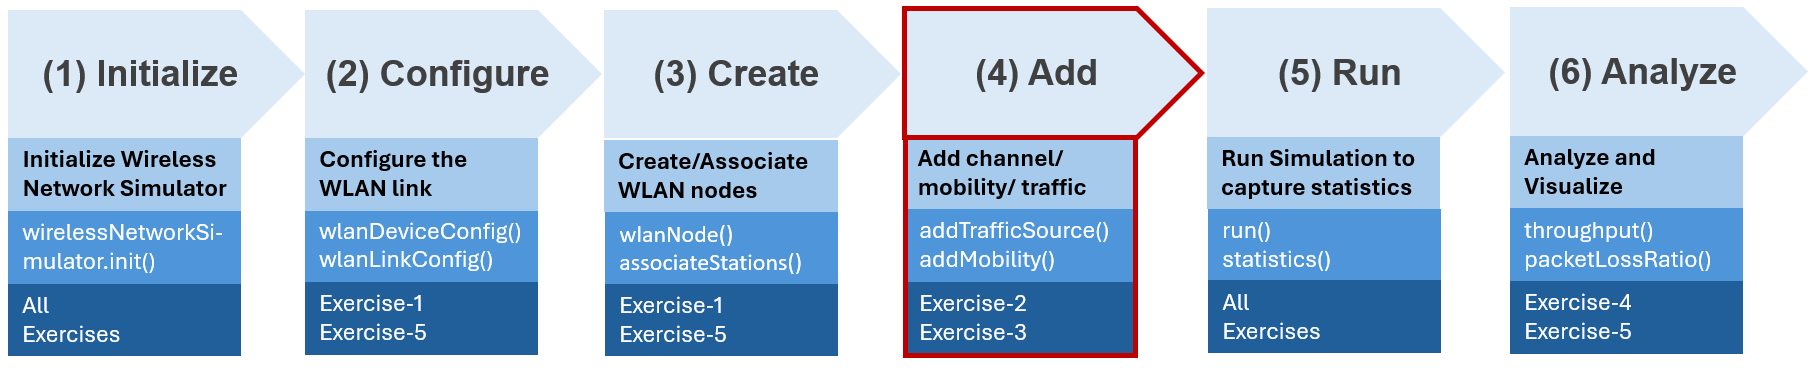

Workflow to perform WLAN Network Modeling

- Generate beacon frames only

- Display some kind of infomation whenever network simulator advances to a new event

Copyright 2024-2025 The MathWorks, Inc

clear all;
clc;
format shortEng;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");

### Physical constants and environment

networkSimulator = wirelessNetworkSimulator.init;

### AP

band                = 5;
channel             = 36;
channelBandwidth    = 20e6;
fc                  = wlanChannelFrequency(channel,band);

TU                  = 1024e-6
simulationDuration  = 10*TU

txPower = 0.0;
txGain  = 0.0;

### Geometry

APPosition  = [0,0,0];
STAPosition = [5.0, 0.0, 0.0];

plotStations (APPosition, STAPosition, fc);

### Create AP

- 802.11n type

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower", txPower, ...
    "TransmitGain",txGain, ...
    "MCS",3, ...
    "BeaconInterval",1, ...
    "InitialBeaconOffset",0);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower",txPower, ...    
    "MCS",3);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

# Task #1/2 Add random mobility on STA

% Use addMobility() function to make the STA move
% Set the first argument to the node object where mobility will be added
% Note : use a BoundaryShape of type 'circle' and speed range [0.1,10]
% 'BoundaryShape', "circle"
% 'SpeedRange', [0.1,10]
% Hint: Clcik the link below and see the "Syntax" section.

### [Help on adding mobility to WLAN nodes ](https://www.mathworks.com/help/wlan/ref/wlannode.addmobility.html)

% <enter code below>
%

### Associate AP with STA

associateStations(AP,STA)

addNodes(networkSimulator,{AP, STA})

# Task #2/2  Scheduling an action for the simulator to perform  

- Do something when NetworkSimulation Time advances

startTime   = 0;
periodicity = 0;

% Periodic, TimeAdvance, OneTime

userData = struct( ...
    ActionType  = "TimeAdvance", ...
    Simulator   = networkSimulator);

% Use scheduleAction() function to get interruption every time the engine advances from one step to the next
% Note : name the callback function "@onTimeAdvance"
% Set the first argument to the node networkSimulator object 
% Set the other arguments in the following sequence  
% @onTimeAdvance,userData,startTime,periodicity
% Hint: Click the link below and see the "Syntax" section.

### [Help on sheduling action ](https://www.mathworks.com/help/releases/R2024b/comm/ref/wirelessnetworksimulator.scheduleaction.html)

% <enter code below>
% 

#### Run the simulation

run (networkSimulator,simulationDuration)

### Visualize statistics

APStatistics  = statistics(AP);
STAStatistics = statistics(STA);

APStatistics.Name;
APStatistics.MAC.TransmittedBeaconFrames
APStatistics.MAC.TransmittedBeaconFrames
STAStatistics.MAC.ReceivedBeaconFrames

####  onTimeAdvance function does the following 

- Plots the time of occurance of event against event #

- It also logs position and velocity of node as simulation progresses 

% Explore and discuss multiple options to create your own callback
% Explore helperFunctions using this approach
% A more docunted API will be available in future releases

function onTimeAdvance(~,userData)

    persistent counter; 
    persistent previousTime;
    persistent curTimeVec;
    
    if isempty(counter)
        counter = 1;
    end

    if isempty(previousTime)
        previousTime = 0;
    end

    if isempty(curTimeVec)
        curTimeVec = NaN(256,1);        
        stem(curTimeVec, 'r*');
        grid on;
    end

    STAName     = userData.Simulator.Nodes{2}.Name;    
    STA_Xpos    = userData.Simulator.Nodes{2}.Position(1);    
    STA_Ypos    = userData.Simulator.Nodes{2}.Position(2);        
    %disp(counter);    
    
    curTime = userData.Simulator.CurrentTime;    
    curTimeVec(counter) = curTime;    
    
    deltaT          = curTime - previousTime;
    previousTime    = curTime;        

    % get number of tx packets at time t = curTime
    numTxPackets = userData.Simulator.Nodes{1}.statistics.PHY.TransmittedPackets;
    
    % plot current time
    stem(curTimeVec, 'r*:');    
    grid on;
    
    fprintf("event#%03d\t time = %.2f us\t dt = %.2f us\t txPackets = %d\t X = %.2f\t Y = %.6f\n", counter, curTime*1e6, deltaT*1e6, numTxPackets, STA_Xpos, STA_Ypos);
    
    % increment counter
    counter = counter + 1;
end

#### Suggested Experiment:

#### #1

- Set a breakpoint inside the `onTimeAdvance` function

- Press the **Continue** button

- Observe the time of occurrence for the triggered events

- Also, review the logs for node position and velocity 

- Repeat  this process five times